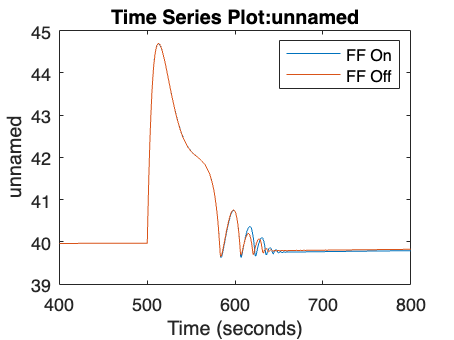

% Clear all variables
load_system("CSTR_Bioreactor_2023_FeedForward.slx");

feedforward(-0.025, 10000)

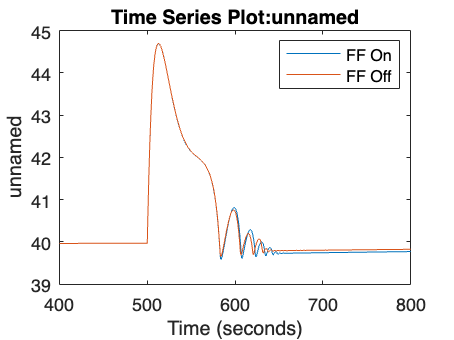

feedforward(-0.025, 17880)

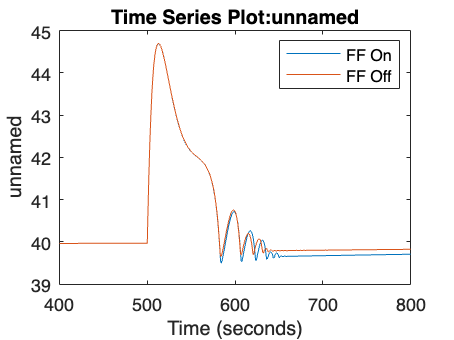

feedforward(-0.025, 40000)

function feedforward(step, gain)
step_time = 500;
mv_dilution_before = 0;
mv_dilution_after = step;

% Load Simulink system, set the parameters, and simulate
load_system("CSTR_Bioreactor_2023_FeedForward.slx");
set_param("CSTR_Bioreactor_2023_FeedForward/feedforward_on", "Gain", num2str(1));
set_param("CSTR_Bioreactor_2023_FeedForward/FFK", "Gain", num2str(gain));
set_param("CSTR_Bioreactor_2023_FeedForward/mv_dilution_step", "Time", num2str(step_time));
set_param("CSTR_Bioreactor_2023_FeedForward/mv_dilution_step", "Before", num2str(mv_dilution_before));
set_param("CSTR_Bioreactor_2023_FeedForward/mv_dilution_step", "After", num2str(mv_dilution_after));
simulate = sim("CSTR_Bioreactor_2023_FeedForward");

% Get timeseries data structures for values and derivatives
pv_ethanolconc = simulate.ScopeData{1}.Values;
pv_biotemp = simulate.ScopeData{2}.Values;
pv_ethanolconc = getsampleusingtime(pv_ethanolconc,400,800);
pv_biotemp = getsampleusingtime(pv_biotemp,400,800);
pv_ethanolconc_feedforward_on = pv_ethanolconc;

load_system("CSTR_Bioreactor_2023_FeedForward.slx");
set_param("CSTR_Bioreactor_2023_FeedForward/feedforward_on", "Gain", num2str(0));
set_param("CSTR_Bioreactor_2023_FeedForward/FFK", "Gain", num2str(gain));
set_param("CSTR_Bioreactor_2023_FeedForward/mv_dilution_step", "Time", num2str(step_time));
set_param("CSTR_Bioreactor_2023_FeedForward/mv_dilution_step", "Before", num2str(mv_dilution_before));
set_param("CSTR_Bioreactor_2023_FeedForward/mv_dilution_step", "After", num2str(mv_dilution_after));
simulate = sim("CSTR_Bioreactor_2023_FeedForward");

% Get timeseries data structures for values and derivatives
pv_ethanolconc = simulate.ScopeData{1}.Values;
pv_biotemp = simulate.ScopeData{2}.Values;
pv_ethanolconc = getsampleusingtime(pv_ethanolconc,400,800);
pv_biotemp = getsampleusingtime(pv_biotemp,400,800);

pv_ethanolconc_feedforward_off = pv_ethanolconc;

plot(pv_ethanolconc_feedforward_on)
hold on 
plot(pv_ethanolconc_feedforward_off)
legend("FF On", "FF Off")
hold off
end

function [k_p, tau, T_d, vmax, dmax, tmax] =  get_foptd(value, derivative, step_time, step)
% Filter spikes in derivative
medfilt_data = medfilt1(derivative.Data);
% Find the maximum gradient (point of inflection)
[dmax_abs, index] = max(abs(medfilt_data));
% Get the gradient, time, and value from the location
dmax = medfilt_data(index);
tmax = derivative.Time(index);
vmax = value.Data(index);
% Get the t values from the steady state values
ss1_intercept = get_time(value.Data(1), vmax, dmax, tmax);
ss2_intercept = get_time(value.Data(end), vmax, dmax, tmax);
% Get the time constant
tau = ss2_intercept-ss1_intercept;
% Get system gain
k_p = (value.Data(end)-value.Data(1))/(step);
% Get time delay
T_d = ss1_intercept-step_time;
end

function time = get_time(y, vmax, dmax, tmax)
    % Given value, gradient, and time,
    % use the inverse of y = gradient(x - time) value 
    time = (y-vmax)/dmax+tmax;
end

